% data=readtable("C:\Users\thoma\Downloads\book1.xlsx")
clear all
data=readtable("C:\Users\thoma\Documents\optionogaktieprisereurostoxx50pronmdex.xlsx",'Sheet','Sheet1','Range','A2:H1602')

data = 1600×8 table
       Date       LastPrice      Volume      SMAVG_15_       Date_1      LastPrice_1     Volume_1     SMAVG_15__1
    __________    _________    __________    __________    __________    ___________    __________    ___________

    27/03/2019     3321.4               0    4.3575e+08    27/03/2019      3321.4       8.3889e+08    2.1031e+09 
    26/03/2019     3319.5      4.3421e+08    4.6148e+08    22/03/2019      3305.7         2.15e+09    2.2099e+09 
    25/03/2019     3300.5      4.0468e+08    4.5612e+08    15/03/2019      3386.1         2.48e+09    2.2339e+09 
    22/03/2019     3305.7      6.6747e+08    4.4874e+08    08/03/2019      3283.6          2.1e+09    2.2152e+09 
    21/03/2019     3367



data=flipud(data)

data = 1600×8 table
       Date       LastPrice      Volume      SMAVG_15_     Date_1    LastPrice_1    Volume_1    SMAVG_15__1
    __________    _________    __________    __________    ______    ___________    ________    ___________

    31/12/2012     2635.9      1.0315e+08     7.003e+08     NaT          NaN          NaN           NaN    
    02/01/2013     2711.3      1.0315e+09    7.2357e+08     NaT          NaN          NaN           NaN    
    03/01/2013     2701.2      8.9775e+08    7.2366e+08     NaT          NaN          NaN           NaN    
    04/01/2013     2709.3      8.2507e+08    7.3206e+08     NaT          NaN          NaN           NaN    
    07/01/2013     2695.6      8.0569e+08    7.3419e+08    

dates=datetime(data.Date,'Convertfrom','excel');
logreturn=[nan;diff(log(data.LastPrice))]*100

logreturn =        NaN
    2.8174
   -0.3706
    0.3005
   -0.5103
   -0.1526
    0.5536
    0.0694
    0.3509
   -0.0968


un=nanvar(logreturn(2:end))

un = 1.2018

S0=1

S0 = 1

K=1

K = 1

r=0.003/251/10000

r = 1.1952e-09

T=[20,40,60,80]

T =     20    40    60    80


op=un/10000

op = 1.2018e-04

for i=1:4
d1=(log(S0/K)+(r+op/2)*T(i))/(sqrt(T(i)*op));
d2=d1-sqrt(op*T(i));
optionspris30=(S0*cdf('Normal',d1,0,1,0,3)-K*exp(-r*T(i))*cdf('Normal',d2,0,1,0,3))*3300
end

optionspris30 = 64.5377

optionspris30 = 91.2610

optionspris30 = 111.7603

optionspris30 = 129.0368


% data=readtable("C:\Users\thoma\Downloads\book1.xlsx")
clear all
data=readtable("C:\Users\thoma\Documents\optionogaktieprisereurostoxx50pronmdex.xlsx",'Sheet','Sheet1','Range','A2:H1602')

data = 1600×8 table
       Date       LastPrice      Volume      SMAVG_15_       Date_1      LastPrice_1     Volume_1     SMAVG_15__1
    __________    _________    __________    __________    __________    ___________    __________    ___________

    27/03/2019     3321.4               0    4.3575e+08    27/03/2019      3321.4       8.3889e+08    2.1031e+09 
    26/03/2019     3319.5      4.3421e+08    4.6148e+08    22/03/2019      3305.7         2.15e+09    2.2099e+09 
    25/03/2019     3300.5      4.0468e+08    4.5612e+08    15/03/2019      3386.1         2.48e+09    2.2339e+09 
    22/03/2019     3305.7      6.6747e+08    4.4874e+08    08/03/2019      3283.6          2.1e+09    2.2152e+09 
    21/03/2019     3367



data=flipud(data)

data = 1600×8 table
       Date       LastPrice      Volume      SMAVG_15_     Date_1    LastPrice_1    Volume_1    SMAVG_15__1
    __________    _________    __________    __________    ______    ___________    ________    ___________

    31/12/2012     2635.9      1.0315e+08     7.003e+08     NaT          NaN          NaN           NaN    
    02/01/2013     2711.3      1.0315e+09    7.2357e+08     NaT          NaN          NaN           NaN    
    03/01/2013     2701.2      8.9775e+08    7.2366e+08     NaT          NaN          NaN           NaN    
    04/01/2013     2709.3      8.2507e+08    7.3206e+08     NaT          NaN          NaN           NaN    
    07/01/2013     2695.6      8.0569e+08    7.3419e+08    

dates=datetime(data.Date,'Convertfrom','excel');
logreturn=[nan;diff(log(data.LastPrice))]*100

logreturn =        NaN
    2.8174
   -0.3706
    0.3005
   -0.5103
   -0.1526
    0.5536
    0.0694
    0.3509
   -0.0968



% logreturn=[nan;100*diff(log(data.LastPrice))]
initialvaerdier = [1,0.2]

initialvaerdier =     1.0000    0.2000


Ovenfor=[inf inf]

Ovenfor =    Inf   Inf


any(logreturn>5)

ans = logical
   0


Nedenfor=[0 0]

Nedenfor =      0     0


T=size(logreturn,1)

T = 1600

A=[0 0];
b=1;
w = .05*.9.^(0:T-2);
backCast= w*logreturn(2:end).^2;
backCast=0.01

backCast = 0.0100

options = optimset('fmincon');
options.Display = 'iter';
options.Algorithm = 'sqp';
options.Functiontolerance=1/100000000000;
options.TolCon=1/100000000000;
%  estimates = fmincon(@kv,initialvaerdier,A,b,[],[],Nedenfor,Ovenfor,[],options,logreturn(2:1500),backCast);
%  initialvaerdier2=[estimates]
 [estimates2,fval,exitflag,output,lambda,gradient,hessian] = fmincon(@kv,initialvaerdier,A,b,[],[],Nedenfor,Ovenfor,[],options,logreturn(2:end),backCast);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    2.816042e+03     0.000e+00     1.000e+00     0.000e+00     1.574e+02  
    1          23    2.807170e+03     0.000e+00     2.326e-03     3.720e-01     7.243e+01  
    2          26    2.410927e+03     0.000e+00     1.000e+00     2.884e+01     2.736e+01  
    3          29    2.409816e+03     0.000e+00     1.000e+00     8.425e-01     5.994e+00  
    4          32    2.409782e+03     0.000e+00     1.000e+00     5.029e-02     4.343e-01  
    5          35    2.409782e+03     0.000e+00     1.000e+00     5.739e-03     8.209e-03  
    6          38    2.409782e+03     0.000e+00     1.000e+00     8.179e-05     2.804e-04  
    7          41    2.409782e+03     0.000e+00     1.000e+00     6.289e-06     2.549e-05  



un=estimates2(:,1)/10000

un = 1.1970e-04

S0=data.LastPrice(end)

S0 = 3.3214e+03

r=0.001235

r = 0.0012

T=[22,22,22,22,51,51,86,177];
K=[3300,3325,3350,3375,3300,3375,3300,3300];
T=T/251

T =     0.0876    0.0876    0.0876    0.0876    0.2032    0.2032    0.3426    0.7052


op=un*251

op = 0.0300

for i=1:8
d1(i)=(log(S0./K(i))+(r+op./2).*T(i))./(sqrt(T(i).*op));
d2(i)=d1(i)-sqrt(op*T(i));
optionspris30(i)=(S0*cdf('Normal',d1(i),0,1)-K(i)*exp(-r*T(i))*cdf('Normal',d2(i),0,1))
end

optionspris30 = 79.2183

optionspris30 =    79.2183   66.4311


optionspris30 =    79.2183   66.4311   55.1011


optionspris30 =    79.2183   66.4311   55.1011   45.1929


optionspris30 =    79.2183   66.4311   55.1011   45.1929  114.6694


optionspris30 =    79.2183   66.4311   55.1011   45.1929  114.6694   80.0766


optionspris30 =    79.2183   66.4311   55.1011   45.1929  114.6694   80.0766  145.6457


optionspris30 =    79.2183   66.4311   55.1011   45.1929  114.6694   80.0766  145.6457  204.3952


fakoption=[49.8,36.7,26,15.5,50.3,21.2,58,41.4,92,189.2,90]

fakoption =    49.8000   36.7000   26.0000   15.5000   50.3000   21.2000   58.0000   41.4000   92.0000  189.2000   90.0000


for i=1:8
SE(i)=(optionspris30(i)-fakoption(i)).^2;
end
%total
RMSEtot=sqrt(mean(SE))

RMSEtot = 75.2803

%første måned
RMSEtot=sqrt(mean(SE(1:4)))

RMSEtot = 29.4869

%anden måned
RMSEtot=sqrt(mean(SE(5:6)))

RMSEtot = 61.6842

%tredje måned
RMSEtot=sqrt(mean(SE(7)))

RMSEtot = 87.6457

%sjette måned
RMSEtot=sqrt(mean(SE(8)))

RMSEtot = 162.9952

K=[3300,3325,3350,3375,3300,3375,3300,3300];
3300/S0

ans = 0.9935

3325/S0

ans = 1.0011

3350/S0

ans = 1.0086

3375/S0

ans = 1.0161

SE

SE = 	1.0e+04 *

    0.0865    0.0884    0.0847    0.0882    0.4143    0.3466    0.7682    2.6567


%Fordelt på K
%Total
j=length(K)

j = 8

RMSEtot=sqrt(sum(SE(1:8))./sum(j))

RMSEtot = 75.2803

%K=3300
j=K==3300

j = 1×8 logical array
   1   0   0   0   1   0   1   1


RMSEtot=sqrt(sum(SE(1:8).*j)./sum(j))

RMSEtot = 99.0682

%K=3325
j=K==3325

j = 1×8 logical array
   0   1   0   0   0   0   0   0


RMSEtot=sqrt(sum(SE(1:8).*j)./sum(j))

RMSEtot = 29.7311

%K=3350
j=K==3350

j = 1×8 logical array
   0   0   1   0   0   0   0   0


RMSEtot=sqrt(sum(SE(1:8).*j)./sum(j))

RMSEtot = 29.1011

%K=3375
j=K==3375

j = 1×8 logical array
   0   0   0   1   0   1   0   0


sum(j)

ans = 2

sqrt(sum(SE(1:8).*j))

ans = 65.9403

RMSEtot=sqrt(sum(SE(1:8).*j)./sum(j))

RMSEtot = 46.6268



Volatility = blsimpv(S0,K,r,T,optionspris30)

Volatility =     0.1733    0.1733    0.1733    0.1733    0.1733    0.1733    0.1733    0.1733




r

r = 0.0012

%  mdl=arima(data,1,0)
% es

fval

fval = 2.4098e+03

exitflag

exitflag = 2

output

output = struct with fields:
         iterations: 7
          funcCount: 41
          algorithm: 'sqp'
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the default value of the step size tolerance and constraints are ↵satisfied to within the selected value of the constraint tolerance.↵↵Stopping criteria details:↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-11.↵↵Optimization Metric                                           Options↵max(abs(delta_x./x)) =   4.02e-07                       StepTolerance =   1e-06 (default)↵relative max(constraint violation) =   0.00e+00   ConstraintTolerance =   1e-11 (selected)'
    constrviolation: 0
           stepsize: 6.2894e-06
       lssteplength: 1
      firstorderopt: 2.549

lambda

lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: [0×1 double]
       ineqlin: 0
    ineqnonlin: [0×1 double]
         lower: [2×1 double]
         upper: [2×1 double]


gradient

gradient = 	1.0e+-4 *

    0.2549
   -0.0108


hessian

hessian =   581.0927    0.1557
    0.1557    1.0228


eig(hessian)

ans =     1.0227
  581.0928


any(eig(hessian)<=0)

ans = logical
   0


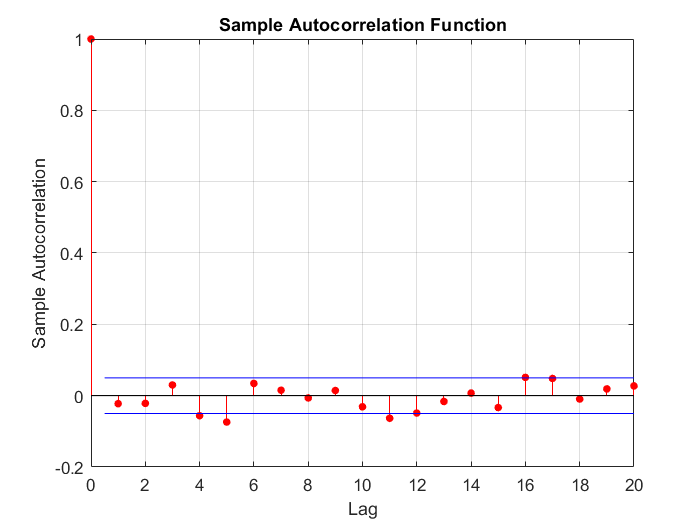

[ll,lls,h,fejlled]=kv(estimates2,logreturn(2:end),backCast);
autocorr(logreturn(2:end))

[acf,lags,bounds]=autocorr(logreturn(2:end))

acf =     1.0000
   -0.0225
   -0.0216
    0.0299
   -0.0563
   -0.0739
    0.0342
    0.0153
   -0.0064
    0.0144


lags =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


bounds =     0.0500
   -0.0500


lmctest(h)

ans = logical
   1


logreturn=logreturn/100

logreturn =        NaN
    0.0282
   -0.0037
    0.0030
   -0.0051
   -0.0015
    0.0055
    0.0007
    0.0035
   -0.0010


h=h/10000

h = 	1.0e+-3 *

    0.0010
    0.1197
    0.1197
    0.1197
    0.1197
    0.1197
    0.1197
    0.1197
    0.1197
    0.1197


h

h = 	1.0e+-3 *

    0.0010
    0.1197
    0.1197
    0.1197
    0.1197
    0.1197
    0.1197
    0.1197
    0.1197
    0.1197



bic=aicbic(ll,length(estimates2),length(logreturn(2:end)))

bic = -4.8156e+03

ll

ll = 2.4098e+03

standardfejl=fejlled./sqrt(h)

standardfejl =     0.0001
  -33.9201
   27.4228
  -46.6843
  -13.9916
   50.5500
    6.3020
   32.0272
   -8.8940
  -45.8399


[h,pValue,stat,cValue]=lbqtest(standardfejl,'lags',5)

h = logical
   1


pValue = 0.0041

stat = 17.2072

cValue = 11.0705

[h,pValue,stat,cValue]=lbqtest(standardfejl.^2,'lags',4)

h = logical
   1


pValue = 0

stat = 120.6534

cValue = 9.4877

mean(standardfejl)

ans = 1.1154

mean(standardfejl.^2)

ans = 9.9937e+03

mean(standardfejl.^3)

ans = -4.5428e+05

mean(standardfejl.^4)

ans = 7.4098e+08

%Test statistik. Normalitet
[h,p,jbstat,critval]=jbtest(standardfejl)

h = 1

p = 1.0000e-03

jbstat = 1.3781e+03

critval = 5.9546


% [h,pvalue,stat,cvalue]=archtest(z)
% z=(logreturn(2:end)-mean(logreturn(2:end)))./sqrt(var(logreturn(2:end)))
% [h,p,jbstat,critval]=jbtest(z)
% 
% plot(z)
% [ts,pv]=ljungbox(z,12)
% [ts,pv]=lmtest(z,12,8294);
% zminus=-z.*1.96
% zplus=z.*1.96
% plot(dates(2:end),zminus,'blue',dates(2:end),zplus,'blue',dates(2:end),z,'red')
% 
% 
% [h,pvalue,stat,cvalue]=archtest(z)
% estimates=estimates'
 



h

h = 1

lls

lls =    -1.3836
    1.0664
    1.0465
    1.1178
    1.0187
    1.1366
    1.0109
    1.0602
    1.0128
    1.1139



% approximation af differentialet for at beregne varians

T=size(logreturn,1)

T = 1600

forskel=0.00001*estimates2

forskel = 	1.0e+-3 *

    0.0120    0.2822


antal=length(estimates2)

antal = 2

bidrag=zeros(T-1,antal);
for i=1:antal
    j=forskel(i)
    delta=zeros(1,antal)
    delta(i)=j
    [~, loglikelidtover]= kv(estimates2+delta,logreturn(2:end),backCast)
    [~, loglikelidtunder]=kv(estimates2-delta,logreturn(2:end),backCast)
    bidrag(:,i)=(loglikelidtover-loglikelidtunder)/(2*j)
    %     J_i=bidrag(i)*bidrag(i)'
end

j = 1.1970e-05

delta =      0     0


delta = 	1.0e+-4 *

    0.1197         0


loglikelidtover =   387.5977
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089


loglikelidtunder =   387.5977
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089


bidrag =          0         0
    0.4177         0
    0.4177         0
    0.4177         0
    0.4177         0
    0.4177         0
    0.4177         0
    0.4177         0
    0.4177         0
    0.4177         0


j = 2.8219e-04

delta =      0     0


delta = 	1.0e+-3 *

         0    0.2822


loglikelidtover =   387.6056
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089


loglikelidtunder =   387.5899
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089
    1.0089


bidrag =          0   27.8920
    0.4177         0
    0.4177         0
    0.4177         0
    0.4177         0
    0.4177         0
    0.4177         0
    0.4177         0
    0.4177         0
    0.4177         0


I=bidrag'*bidrag/T

I =     0.1742         0
         0    0.4862


%Så skal J findes
J=hessian_beggesider(@kv, estimates2, logreturn(2:end), backCast)

J =  -557.5119   -0.0001
   -0.0001    1.0000


J=J/T

J =    -0.3484   -0.0000
   -0.0000    0.0006


Jinv=J\eye(length(J))

Jinv = 	1.0e+03 *

   -0.0029   -0.0000
   -0.0000    1.6000



% Så kombineres J og I ved sandwhichformlen
vcv=Jinv*I*Jinv/T

vcv =     0.0009   -0.0001
   -0.0001  777.9665


se=sqrt(diag(vcv))

se =     0.0299
   27.8921


estimates2

estimates2 =     1.1970   28.2188


name={'gamma';'lambda'};
gamma=estimates2(:,1)

gamma = 1.1970

lambda=estimates2(:,2)

lambda = 28.2188


%Simulation af indeksværdi
gamma=estimates2(:,1)/(100.^2) 

gamma = 1.1970e-04

%Først trækker jeg noge tilfældige tal fra normalfordelingen
tilfaeldige=randn(502,100000);
%Så allokere jeg plads til variablerne
omega=estimates2(:,1)/(100.^2)

omega = 1.1970e-04

sigma2=zeros(502,100000);
sigma2(1,:)=h(end)./10000

sigma2 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0        

y=zeros(502,100000);
S=zeros(502,100000);
%Jeg definerer den samlede portefølje til en i første periode. 
S(1,:)=data.LastPrice(end)

S =     3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0   

S0=data.LastPrice(end)

S0 = 3.3214e+03

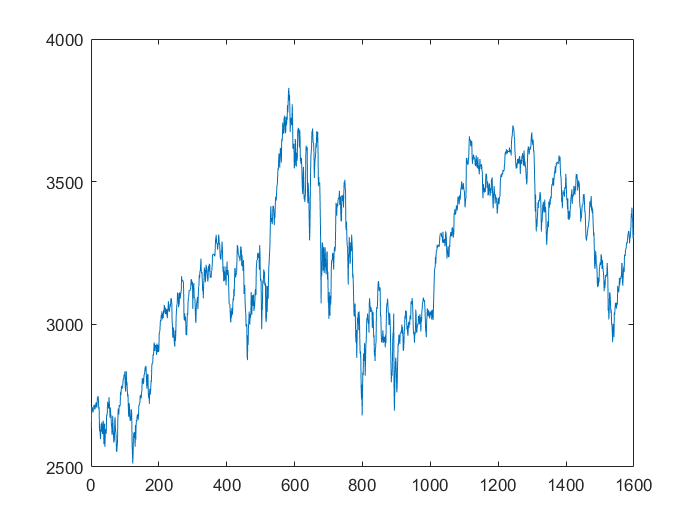

%  S(1,:)=data.PX_LAST(end);
%  r=zeros(502,10000);
 %Jeg simulerer y(t)=r-1/2*h(t)+epsilon(t). Som afkast under Q
 %Den betingede varians er givet ved
 %h(t)=omega+alpha*epsilon(t-1)^2+beta*h(t-1)
 plot(data.LastPrice)

r=(1+0.001235)^(1/251)-1;
akumuleretafkast=zeros(453,100000);
 tic
for j=1:100000
    for i=2:453
        %sigma2 er den betingede varians
        sigma2(i,j)=omega;
        %y er det daglige afkast givet ved 
        y(i,j)=sqrt(sigma2(i,j))*tilfaeldige(i,j)+(r)-sigma2(i,j)/2;
        %jeg samler de daglige afkast i r og tager tilsidst eksponential
        %funktionen til r i de enkelte periode.
         akumuleretafkast(i,j)=y(i,j)+akumuleretafkast(i-1,j);
        S(i,j)=S0*exp(akumuleretafkast(i,j));
    end
end
toc

Elapsed time is 198.950088 seconds.


x=-250:250;
K=S0+x

K =     3.0714    3.0724    3.0734    3.0744    3.0754    3.0764    3.0774    3.0784    3.0794    3.0804    3.0814    3.0824    3.0834    3.0844    3.0854    3.0864    3.0874    3.0884    3.0894    3.0904    3.0914    3.0924    3.0934    3.0944    3.0954    3.0964    3.0974    3.0984    3.0994    3.1004


option=zeros(1,501)

option =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


tic
R=r+1

R = 1.0000

for i=1:501
option(i)=mean(max(S(22,:)-K(i),0))*exp(-((R)^22-1));
end
toc

Elapsed time is 0.772275 seconds.


option

option =   254.3934  253.4559  252.5191  251.5832  250.6479  249.7135  248.7799  247.8471  246.9153  245.9843  245.0542  244.1250  243.1966  242.2692  241.3425  240.4167  239.4917  238.5677  237.6445  236.7224  235.8012  234.8810  233.9618  233.0436  232.1264  231.2102  230.2950  229.3807  228.4674  227.5551


Volatility = blsimpv(S0,K,r,22/251,option)

Volatility =     0.1721    0.1721    0.1720    0.1720    0.1720    0.1720    0.1719    0.1719    0.1719    0.1718    0.1718    0.1718    0.1718    0.1717    0.1717    0.1717    0.1717    0.1716    0.1716    0.1716    0.1716    0.1715    0.1715    0.1715    0.1715    0.1715    0.1714    0.1714    0.1714    0.1714


implieds=Volatility

implieds =     0.1721    0.1721    0.1720    0.1720    0.1720    0.1720    0.1719    0.1719    0.1719    0.1718    0.1718    0.1718    0.1718    0.1717    0.1717    0.1717    0.1717    0.1716    0.1716    0.1716    0.1716    0.1715    0.1715    0.1715    0.1715    0.1715    0.1714    0.1714    0.1714    0.1714


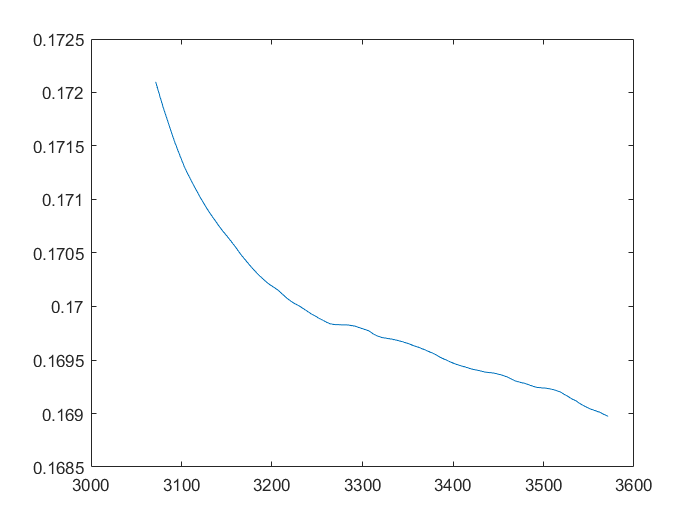

plot(K,implieds)

% alpha=estimates2(:,3)
% lambda=estimates2(:,4)
gamma=estimates2(:,1)

gamma = 1.1970

standardafvigelse=[se']

standardafvigelse =     0.0299   27.8921


parametre=[gamma lambda] 

parametre =     1.1970   28.2188


ttest=parametre'./se

ttest =    39.9721
    1.0117


table(name, parametre',standardafvigelse',ttest)

ans = 2×4 table
      name       Var2       Var3      ttest 
    ________    ______    ________    ______

    'gamma'      1.197    0.029947    39.972
    'lambda'    28.219      27.892    1.0117



K=K/S0

K =     0.9247    0.9250    0.9253    0.9256    0.9259    0.9262    0.9265    0.9268    0.9271    0.9274    0.9277    0.9280    0.9283    0.9286    0.9289    0.9292    0.9295    0.9298    0.9302    0.9305    0.9308    0.9311    0.9314    0.9317    0.9320    0.9323    0.9326    0.9329    0.9332    0.9335


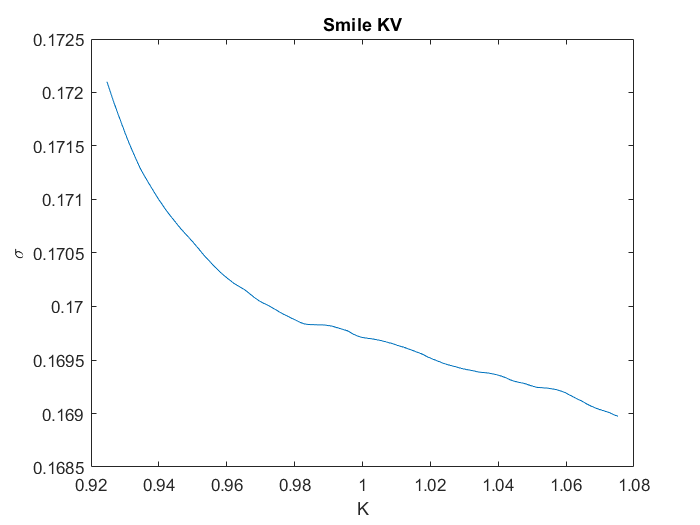


plot(K,implieds)
title('Smile KV')
xlabel('K')
ylabel('\sigma')


%Simulation af indeksværdi



function [ll,lls,h,fejlled]=kv(parameters, logreturn, backCast)

c=parameters(1);
lambda1=parameters(2);
T=size(logreturn,1);
h=zeros(T,1);
h(1)=backCast;
fejlled=zeros(T,1);
r=(1+0.001235)^(1/(251))-1;
fejlled=logreturn-r*100+h/2-lambda1*sqrt(h);
for i=2:T
    h(i)=c;
    
end
% v=length(logreturn)-length(parameters);
% if v<50
%     v = 2 + exp(v);
% else
%     v = 50 + log(v);
% end
 lls= 0.5*(log(pi*2)+log(h)+fejlled.^2./h);
% lls=1/2*(log(h)+(v+1)*log(1+fejlled.^2./(h.*(v-1))));

ll=  sum(lls);
end

% funktion til varians
function H= hessian_beggesider(funktion,parametre,varargin)
if size(parametre,2)>size(parametre,1)
    parametre=parametre';
end

f=feval(funktion,parametre,varargin{:});
h=abs(parametre)*0.00001;
parametreh=h+parametre;
h=parametreh-parametre;
h=diag(h);

antal=size(parametre);

afledtep=zeros(antal);
afledten=zeros(antal);
for i=1:antal
    afledtep(i)=feval(funktion, parametre+h(:,i),varargin{:});
    afledten(i)=feval(funktion, parametre-h(:,i),varargin{:});
end
anafledtep=zeros(antal);
anafledten=zeros(antal);

for j=1:antal
    for i=j:antal
        anafledtep(i,j)=funktion(parametre+h(:,j)+h(:,i),varargin{:});
        anafledtep(j,i)=anafledtep(i,j);
        anafledten(i,j)=funktion(parametre-h(:,j)-h(:,i),varargin{:});
        anafledten(j,i)=anafledten(i,j);
    end
end
H=zeros(antal);
diagonal=diag(h);
GH=diagonal*diagonal';
for i=1:antal
    for j=i:antal
        H(i,j)=(anafledtep(i,j)+anafledten(i,j)-afledtep(i)-afledten(i)-afledtep(j)-afledten(j)+f+f)/GH(i,j)/2;
        H(j,i)=H(i,j);
    end
end
end
